# Pressure & Velocity

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

In fluid dynamics, understanding the links between pressure, velocity, energy, and power is essential because they are the driving mechanisms of fluid flow.

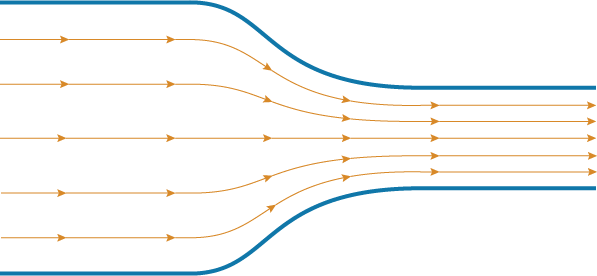

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build some familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is pressure?

Pressure is a measure of the force a fluid exerts on the wall of its container. On a microscopic scale, the fluid particles impact the container wall and bounce back from it. Because the fluid has many particles, all those discrete impacts can be added together over time. The measure of the intensity of those impacts is the pressure, denoted   $p$ or $P$. 

  **Try.** Run the following function to visualize fluid particle impact on a surface.

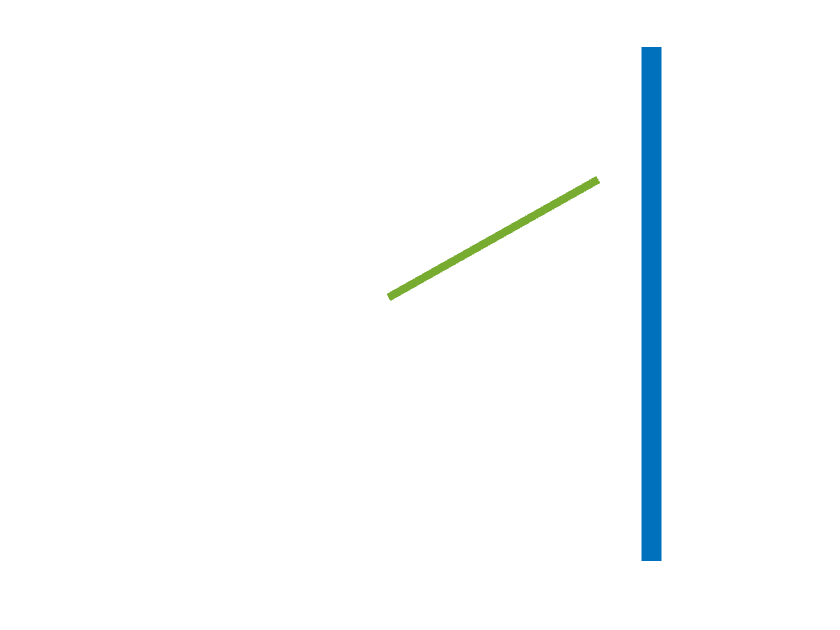

 
PlotPressure

Pressure is a scalar quantity in the whole fluid domain and is dimensionally equivalent to a force per surface unit. The total resulting force on a surface can be estimated using the following relationships:


$$F = P\times S
$$


Where $F$ is the magnitude of the force, $P$ is the pressure and $S$ on which the pressure is applied.

### Absolute vs. Relative pressure

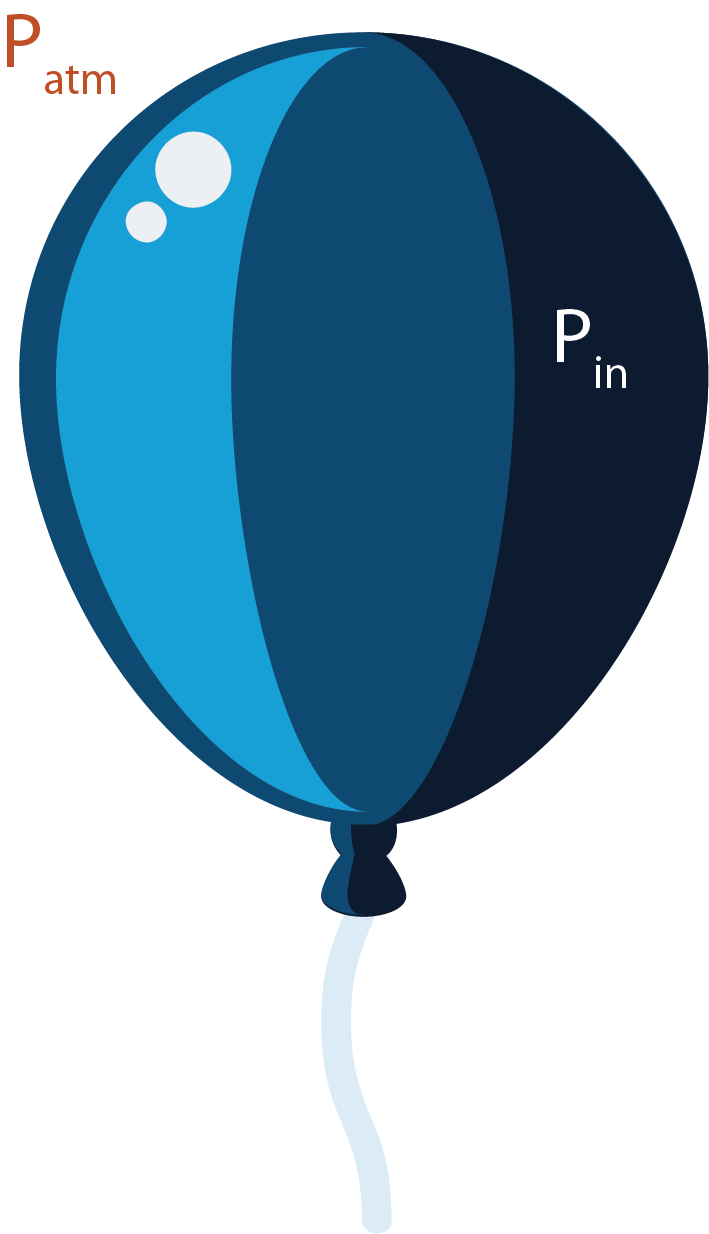

Take a regular rubber air balloon. The pressure inside the balloon   $P_{in}$ is superior to the pressure outside it  $P_{atm}$, giving it its shape. Three forces are acting on the balloon:

- The atmospheric pressure exerts a force toward the center of the balloon.

- The inner pressure exerts a force from the center of the balloon outward.

- The surface tension of the rubber along the balloon’s surface.

The force in the balloon must balance each other; therefore, the surface tension force is a function of the pressure difference between the inside and outside of the balloon. We define the relative pressure such that:


$$P_\text{relative}=P - P_\text{reference}$$


The pressure $P$ represents any pressure and is referred to as absolute pressure so that:


$$P_\text{relative}=P_\text{absolute} - P_\text{reference}$$


The reference pressure is chosen to be the atmospheric pressure so that the relative pressure of the atmosphere is zero and the relative pressure of the balloon is $P_{in} -P_{atm}$.

**Remark: **the most common reference pressure is the atmospheric pressure (1 atm = 101325 Pa), but we could use any arbitrary reference.

Pressure measurements are often relative measurements. For example, a bike tire pump will show zero pressure if your tire is completely deflated. It does not mean that the absolute pressure inside the tire is zero but that the air inside is at the same pressure as the atmosphere.

**Remark: **because absolute pressure is a macroscopic measure of the fluid impact on a surface $P_\text{absolute} \geq 0$, there is either no impact or some impact, but a negative number of impacts does not make physical sense. However, because the relative pressure is an offset of pressure, negative relative pressure is possible.

 **Exercise. **Click the following figure to identify the different pressure and measurements presented.

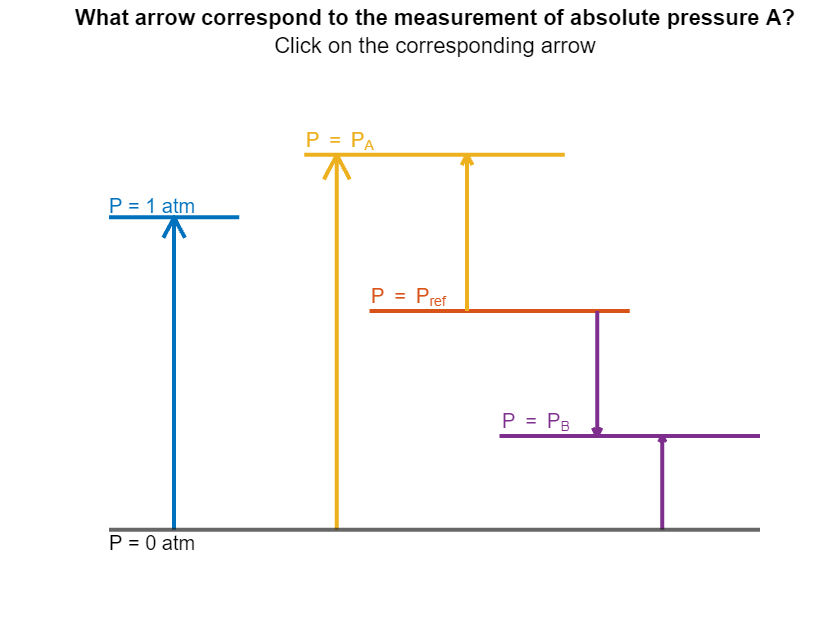

 
IdentifyPressure

### Units

The pressure reference unit in the standard unit system is the Pascal (Pa), named after the French mathematician and physicist [Blaise Pascal](https://en.wikipedia.org/wiki/Blaise_Pascal). However, engineers and scientists use many units depending on their field and application. While an engineer specializing in hydraulics applications might use "meter of water" as the unit of choice, an aerodynamicist might use psi (pound per square inches) or Pa.

  **Try. **Run the following code to create a unit system and get information about Pascals.

units = symunit;
unitInfo(units.Pa)


pascal - a physical unit of pressure. ['SI']

Get all units for measuring 'Pressure' by calling unitInfo('Pressure').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



  **Try. **Following the prompt from `unitInfo`, explore all units of pressure available.

unitInfo("Pressure")


All units of dimension 'Pressure':

at - technical atmosphere
atm - standard atmosphere
Ba - barye 
bar - bar
cmH2O - centimeter of water (conventional)
cmHg - centimeter of mercury (conventional)
ftH2O - foot of water (conventional)
ftHg - foot of mercury (conventional)
inH2O - inch of water (conventional)
inHg - inch of mercury (conventional)
ksf - kip per square foot
ksi - kip per square inch
mH2O - meter of water (conventional)
mHg - meter of mercury (conventional)
mmH2O - millimeter of water (conventional)
mmHg - millimeter of mercury (conventional)
Pa - pascal ['SI']
psf - pound force per square foot
psi - pound force per square inch
pz - pieze
Torr - torr

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.


Some of the most common units of pressure are:

- mmHg (millimeter of mercury) is used in medicine to measure blood pressure; for example, a blood pressure of 120/80 means that the systolic (while the heart pump) pressure is 120 mmHg and the diastolic (while the heart is at rest in between beats) pressure is 80 mmHg.

- mH2O (meter of water) is used to design large hydraulic systems such as pipelines or hydropower plants.

- atm (atmosphere) corresponds to sea-level atmospheric pressure (1 atm = 101325 Pa). It has been used in chemistry as standard pressure.

- bar (bar) closest multiple of Pascal to the atmosphere (1 bar = 100000 Pa) is now used to define the standard pressure in chemistry.

- psi is commonly used as empirical units of pressure.

You should get familiar with some of the most common units you might encounter in fluid mechanics: Pa, bar, atm, and psi.

You should get familiar with some of the most common units that you might encounter in fluid mechanics: Pa, bar, atm, and psi.

 **Exercise. **Use [`unitConversionFactor`](https://www.mathworks.com/help/symbolic/unitconversionfactor.html) to compute the conversion factor between...  bar to Pa, atm to Pa, bar to psi, and atm to psi.

bar2Pa = unitConversionFactor(units.bar,units.Pa)

$$bar2Pa = 100000$$

    b) atmosphere (atm) and Pascals (Pa)

atm2Pa = unitConversionFactor(units.atm,units.Pa)

$$atm2Pa = 101325$$

    c) bar (bar)  and pound per square inch (psi)

bar2psi = unitConversionFactor(units.bar,units.psi)

$$bar2psi = 14.5038$$

    d) atmosphere (atm) and pound per square inch (psi)

atm2psi = unitConversionFactor(units.atm,units.psi)

$$atm2psi = 14.6959$$


 
CheckUnitConversionFactor(bar2Pa, atm2Pa, bar2psi, atm2psi);

Good job! You found the right convertion unit in between the atm, bar, Pa and psi.


  **Try. **Explore all units of pressure available. Feel free to explore more units, such as mH2O and mmHg, on your own.

% You can used this space to try computing any other pressure conversion factor:


So far, we have learned about the different units of pressure, how to define them, and how to compute the conversion factor from one unit to another. MATLAB can rewrite any symbolic expression expressed in one unit into another compatible unit. Two compatible units are units that are linked by a dimensionless conversion factor. For example, meter (m) and Fahrenheit (F) are two incompatible units, while inch (in) and meter (m) are compatible units.

  **Try. **Convert inches in meters.

inchesInMeter = rewrite(units.in, units.m)

$$inchesInMeter = 0.0254\,m$$

 **Exercise. **Use [`rewrite`](https://www.mathworks.com/help/symbolic/rewrite.html?searchHighlight=rewrite&s_tid=srchtitle_rewrite_1) to convert Pascals into Newton and meter into `pascals`.

Pascals = rewrite(units.Pa, [units.m units.N]);
 
CheckDecompositionUnits(Pascals);

Good job! Pressure units are equivalent to unit of force per unit of surface. And Pascals is equivalent to Newton per square meter.


 **Reflect**. Can ou make link in between the answer for the previous exercise and this equation from the introduction? 

## Bernoulli's Principle

### Definition

The Bernoulli equation is a fundamental equation of fluid dynamic that describes the relationship between pressure, velocity, and elevation change in the fluid. This equation is named after the Swiss mathematician Daniel Bernoulli, who formulated it in 1738. The Bernoulli equation states that the total pressure of a fluid system is constant along a streamline with the total pressure defined by:


$$P_\text{total}= P+
\frac{1}{2}\rho v^2+
\rho g z \qquad(\star)$$


where $P$ represents the static pressure of the fluid, $\rho$ its density, $v$ its velocity, $g$ gravitational acceleration, $z$ the elevation and:

- $\frac{1}{2}\rho v^2$ is the dynamic pressure. It is the pressure that is due to the bulk motion of the fluid.

- $\rho g z$ is the hydrostatic pressure; it is the pressure that is due to the gravitational potential. The component is important in a fluid system with liquid because of its high density and is often neglected with gases.

**Streamline: **In fluid dynamics, the mathematical definition of a streamline is the flow line tangent to the velocity vector at every point. Physically, it represents the path that a small, frictionless particle would follow if it were to flow in this fluid.

We should verify that each term of Bernoulli's equation is consistent with a unit of pressure.

  **Try. **Check if the dynamic pressure term is consistent as a unit of pressure.

units = symunit;
DynamicPressureUnits = units.kg/units.m^3*(units.m/units.s)^2;
checkUnits(DynamicPressureUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1


 **Exercise. **Similarly, check that the hydrostatic pressure term is consistent as a unit of pressure.

% Your code goes in the next line:
HydrostaticPressureUnits = units.kg/units.m^3*units.m/units.s^2*units.m;;

% Check the units consistency:
  checkUnits(HydrostaticPressureUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1


 **Reflect**. Reflect on the similarity in between the term in equation $(\star)$ and the definition of work, kinetic energy, and potential energy.

- Work: $W = \int P dV$

- Kinetic energy: $E_k = \frac{1}{2}mv^2$

- Potential energy: $E_p = mgz$

The Bernoulli equation $(\star)$ is often written in term of hydraulic head $H$:


$$H = \frac{P}{\rho g} + \frac{v^2}{2 g} + z
\quad\quad
(\spadesuit)$$


### **Pressure along a streamline**

We are considering the streamline of a free-flowing fluid between point A and point B. The velocity at points A and B and the elevation change are known. We will express the pressure in relative pressure, and the reference pressure is equal to the absolute pressure at point A, so its relative pressure is 0. We are trying to compute the pressure at point B.

  **Try.** Use the slider below to visualize a streamline between points A and B of a fluid flow with an elevation difference.

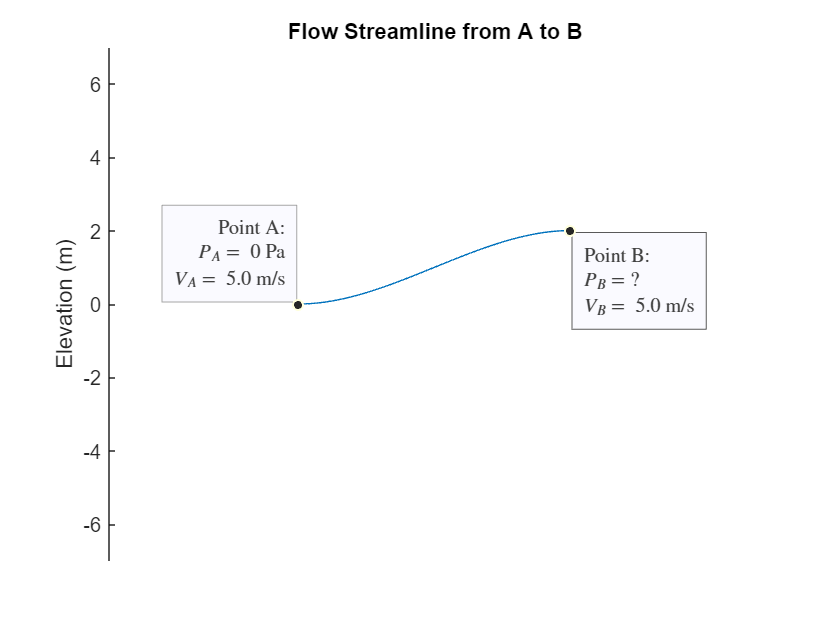

% Select a fluid:
rho = 1000*units.kg/units.m^3;

% Point A data:
VelocityA = 5* units.m/units.s;
PressureA = 0*units.Pa;

% Point B data:
VelocityB = 5*units.m/units.s;

% Elevation change and gravity:
dh = 2* units.m;
g = 9.81*units.m/units.s^2;

 
PlotStreamline(dh,VelocityA,VelocityB)

We use the symbolic math toolbox to define the total pressure at points A and B as a function of the problem variable.

 **Exercise.** Write the total pressure at point A and point B.

syms PressureB

% Your code goes here:
TotalPressureA = PressureA + 1/2*rho*VelocityA^2

$$TotalPressureA = 12500\,\frac{\mathrm{kg}}{m\,s^{2}}$$

TotalPressureB = PressureB + 1/2*rho*VelocityB^2 + rho*g*dh

$$TotalPressureB = \mathrm{PressureB}+32120\,\frac{\mathrm{kg}}{m\,s^{2}}$$

  CheckFreeStreamBernoulli(TotalPressureA,TotalPressureB,PressureA,VelocityA,VelocityB,rho,g,dh)

We can define the equality of the total pressure and solve for the pressure at point B.

  **Try. ** [Solve](https://www.mathworks.com/help/symbolic/sym.solve.html) the pressure at point B using the equation $(\star)$.

% Define the equation to solve:
Eqn = TotalPressureB == TotalPressureA;
PressureB = solve(Eqn, PressureB)

$$PressureB = -19620\,\frac{\mathrm{kg}}{m\,s^{2}}$$

  **Try.** Rewrite the pressure in your unit of choice.

% Select your choise of pressure:
UnitChoice = units.psi;

% Rewrite the upstream and downstream pressure in that unit:
PressureB = vpa(rewrite(PressureB, UnitChoice))

$$PressureB = -2.8456\,\mathrm{psi}$$

### **Application: Converging Pipe Flow**

We just considered the flow along the streamline of a free-flowing fluid. In this section, we are considering the flow in a converging pipe of upstream diameter $D_A$ and downstream diameter $D_B$, the inflow velocity is $V_A$ and the fluid is incompressible.

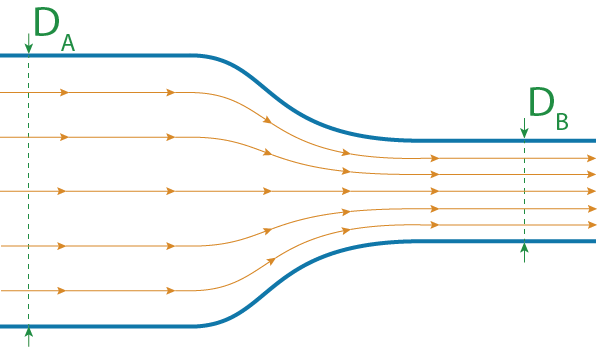

 **Exercise.** Considering that the mass is conserved in the pipe, express the velocity at point B as a function of the velocity at point A and the diameters.

% Define the problem parameters: 
syms DiameterA DiameterB VelocityA PressureA PressureB rho

% You code goes here:
VelocityB = VelocityA*DiameterA^2/DiameterB^2;

 
CheckVelocityConvergentPipe(VelocityB)

Good job! You expressed the velocity at point B correctly.


Following the same step as the previous section, we can express the total pressure at points A and B.

 **Exercise.** Considering no elevation change, express the total pressure at points A and B.

TotalPressureA = PressureA + 0.5*rho*VelocityA^2;
TotalPressureB = PressureB + 0.5*rho*VelocityB^2;

 
CheckTotalPressureConvergentPipe(TotalPressureA, TotalPressureB)

Good job! You expressed both total pressure correctly.


  **Try.** Solve the equation for $\Delta P = P_B - P_A$

PressureDifference = solve( TotalPressureA == TotalPressureB , PressureB ) - PressureA

$$PressureDifference = 0.5000\,{\mathrm{VelocityA}}^{2}\,\rho -\frac{0.5000\,{\mathrm{DiameterA}}^{4}\,{\mathrm{VelocityA}}^{2}\,\rho }{{\mathrm{DiameterB}}^{4}}$$

PressureDifference = simplify(PressureDifference)

$$PressureDifference = -\frac{0.5000\,{\mathrm{VelocityA}}^{2}\,\rho \,\left({\mathrm{DiameterA}}^{4}-{\mathrm{DiameterB}}^{4}\right)}{{\mathrm{DiameterB}}^{4}}$$

 **Reflect**. Knowing that $D_A > D_B$ should we expect the pressure to increase or decrease along the converging pipe? This counter-intuitive result is referred to as Bernoulli's principle.

### **Application: Pitot tube**

A pitot tube is a device that is used to measure velocity with a fluid that is particularly used in aviation. It usually consists of a thin hollow tube pointed toward the fluid flow. For example, in the following figure, the NH-90's pitot tube is oriented toward to cockpit of the airplane. 

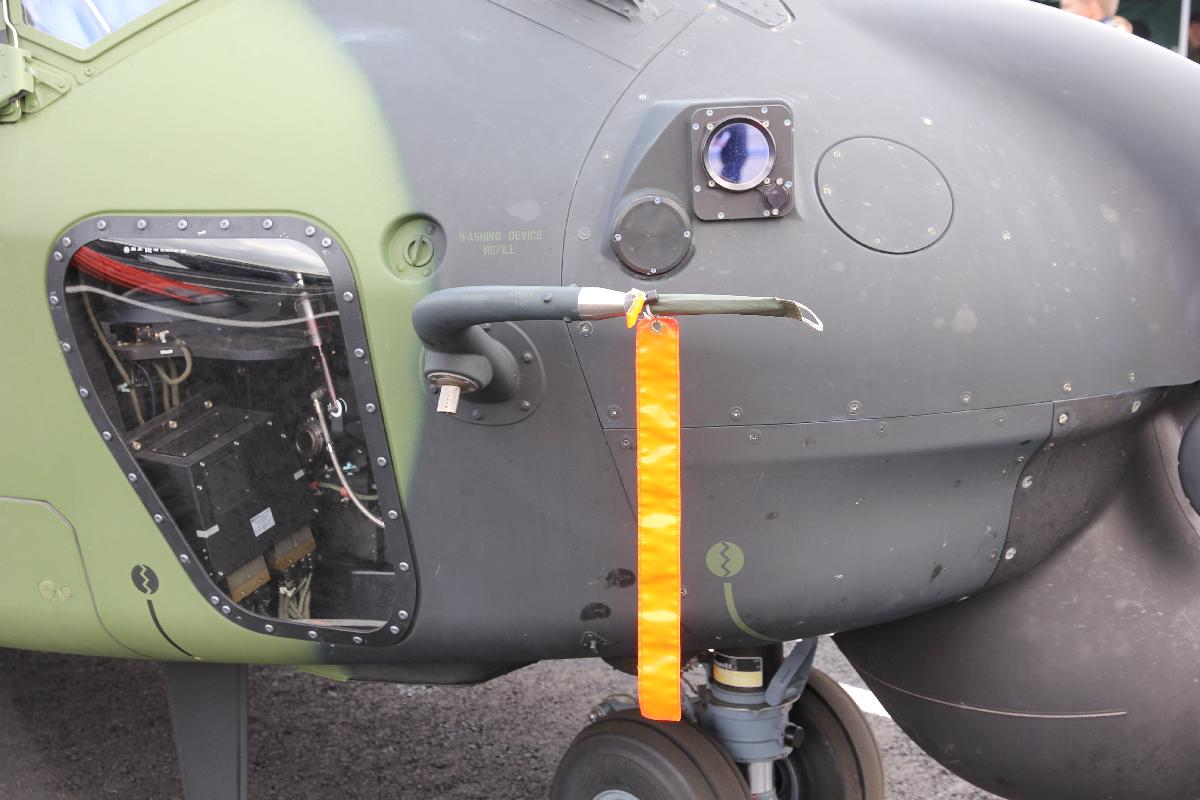

An NH-90's pitot tube, [Wikimedia](https://commons.wikimedia.org/wiki/File:NH90_(NH-211)_Kokonaisturvallisuus_2015_03_pitot_tube.JPG)

There are multiple types of Pitot tubes. In this script, we are studying a Pitot-static tube. This device presents two openings, one in the front and one on the side. One of those openings is used to define the stagnation pressure:


$$P_\text{stagnation} = P_\text{static} + \frac{1}{2}\rho v^2 $$


This pressure represents the pressure the fluid would have if it came to a sudden stop. The following figure presents a schematic representation of the Pitot-static tube with the pressure gauge.

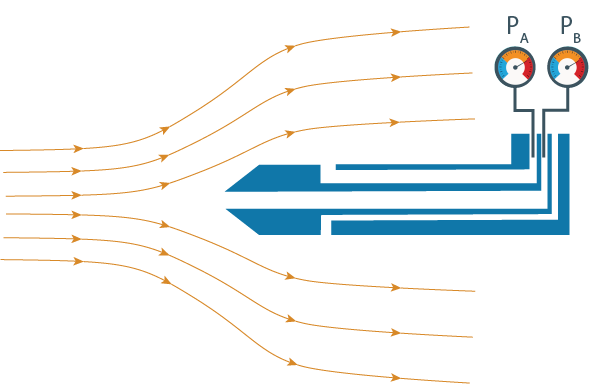

 **Exercise. **Identify the kind of pressure that is measured by each of the pressure gauges.

CheckPressurePitot(GaugeA="Static",GaugeB="Stagnation");

Good job! You have identified the pressure correctly.


Now that both pressures are known, we are considering the difference in pressure between the two gauges:  $\Delta P = P_B - P_A$

 **Exercise. **Based on your answer to the previous question, what pressure is equal to $\Delta P = P_B - P_A$ represents?

CheckPressureDifferencePitot("Dynamic");

Good job! The pressure difference is the dynamic pressure.


 **Exercise.** Express the free-stream velocity  `freeStreamVelocity` as a function of $\Delta P= P_B - P_A$

% Declare the parameters of the problem:
syms StaticPressure rho AirVelocity

% Your code goes here:
PressureA = StaticPressure;
PressureB = StaticPressure + 1/2*rho*AirVelocity^2;

% Compute the pressure difference:
PressureDifference = PressureB - PressureA

$$PressureDifference = 0.5000\,{\mathrm{AirVelocity}}^{2}\,\rho$$

 
CheckPressureDiffPitot(PressureDifference)

Good job! You expressed the pressure difference correctly.


  **Try.** Plot the pressure difference as a function of the airspeed at a density of 1.14 kg/m3 for airspeed from 0 to 100 m/s.

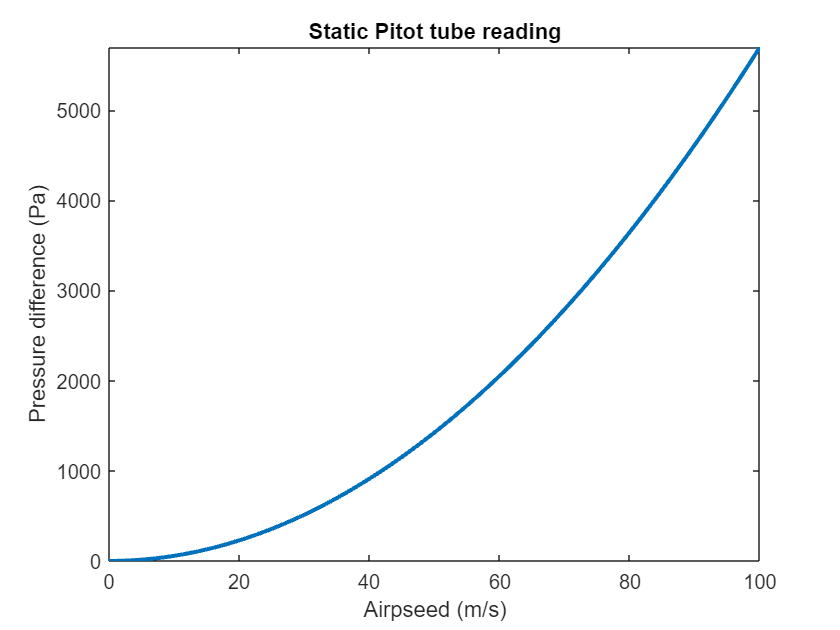

% Plot the results if the previous exercise was completed:
if PressureDifference ~= 0
    figure
    PressureDifference(AirVelocity) = subs(PressureDifference, rho, 1.14);
    fplot(PressureDifference,[0 100],LineWidth=2)
    title("Static Pitot tube reading")
    ylabel("Pressure difference (Pa)")
    xlabel("Airpseed (m/s)")
end

### **Application: Lift generation around an airfoil**

We are studying the lift generation around an airfoil applied to a NACA-2412 airfoil. The NACA airfoils are a series of wing profiles developed by the National Advisory Committee for Aeronautics (NACA) in the 1920s and 1930s. These airfoils have been thoroughly studied and have been the basis of airfoil design for decades and are still used today. The NACA-2412 is a wing profile with a max camber of 2%, located at 40% of the chords with a thickness of 12%, hence 2412. Each NACA airfoil is defined by 4 or 5 digits representing the geometrical features of the airfoil.

  **Try. **Plot the NACA-2412 profile.

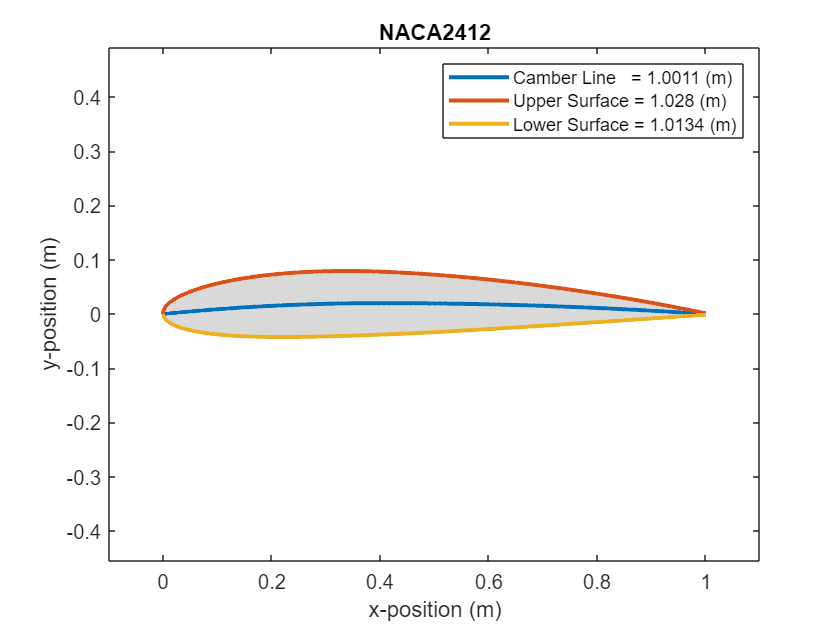

 
[~,~,~] = NACA4digits(12,2,40);

For more information about the NACA airfoil, please visit this module's documentation of the `NACA4digits` function.

The NACA-2412 is a common airfoil used for small aircraft and control surfaces like the [Cessna-172](https://en.wikipedia.org/wiki/Cessna_172). It is usually used for applications with relatively low airspeed, high lift, and low drag, around 120 knots. Airfoils obstruct the flow, and when the aircraft is at a certain airspeed, the air velocity above and below the airfoil is slightly different. We can define the velocity over and under the airfoil as follow:


$$V=V_\text{cruise}+V'$$


where, $V$ is the velcity, $V_\text{cruise}$ is the cruise velocity of the aircraft and $V'$ is the difference in velocity. There is a streamline going from downstream to the upper part of the airfoil and another going from downstream to the lower part of the airfoil. Therefore, we can write the Bernoulli equations between those points:


$$P_\text{total,downstream}=P_\text{total,upper}=P_\text{total,lower}$$


Hence,


$$P_\text{upper} + \frac{1}{2}\rho V_\text{upper}=P_\text{lower} + \frac{1}{2}\rho V_\text{lower}$$


 **Exercise. **Write the total pressure over and under the airfoil.

% Set the problem unknown:
syms UpperVelocity LowerVelocity UpperPressure LowerPressure rho

% Write your code here:
UpperTotalPressure = UpperPressure + 1/2*rho*UpperVelocity^2;
LowerTotalPressure = LowerPressure + 1/2*rho*LowerVelocity^2;

% Define the pressure difference:
PressureDifference = solve(UpperTotalPressure == LowerTotalPressure, UpperPressure) - LowerPressure

$$PressureDifference = 0.5000\,{\mathrm{LowerVelocity}}^{2}\,\rho -0.5000\,{\mathrm{UpperVelocity}}^{2}\,\rho$$

  **Try. **Set a larger velocity along the lower surface than along the upper surfaces.

% Set the value:
ValueRho = 1.14;
ValueUpperVelocity = 50;
ValueLowerVelocity = 50;

% Rewrite the results:
PressureDifferenceValue = subs(PressureDifference, [rho UpperVelocity LowerVelocity],[ValueRho ValueUpperVelocity ValueLowerVelocity])

$$PressureDifferenceValue = 0$$

The difference in pressure over and below the airfoil creates a force that applies vertically to the airfoil.

 **Exercise. **Should the pressure difference be positive or negative to generate an upward "lift" force along the airfoil?

Good job! A negative pressure difference would create an force
 on the airfoil called lift.


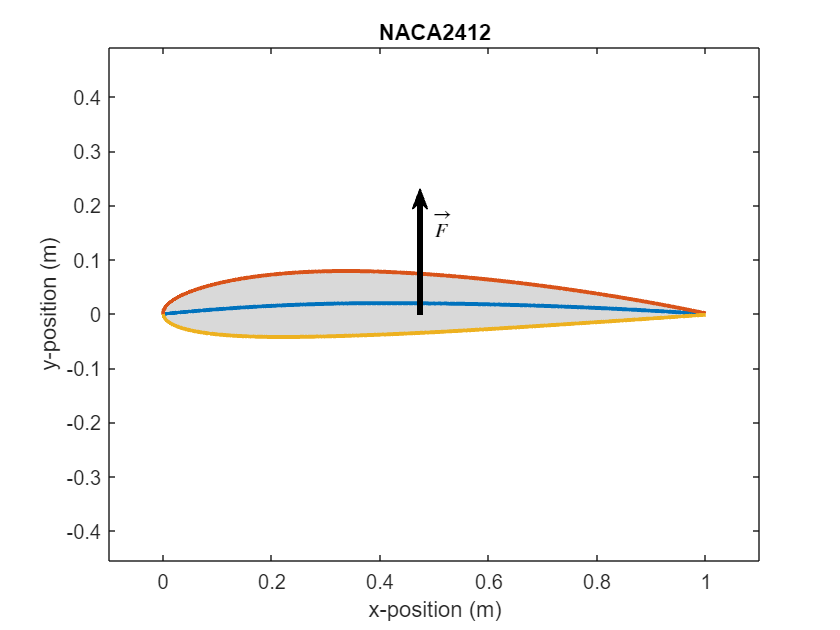

CheckPressureDifferenceSign("Negative")

## Further Exploration

- In this script we only considered ideal flow where the total pressure is conserved along streamline. In all real flow, friction introduce pressure drop, therefore the total pressure decreases along streamline. These pressure loss, often called head losses, can be modelled. Explore [InternalFlow.mlx](matlab:open('./InternalFlow.mlx')) if you want to learn more about realistic flow applied to a house plumbing.

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Helper Functions

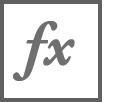**plotStreamline**

- `dh `the elevation change along the streamline

- `v1 `the upstream velcity

- `v2 `the downstream velocity

function PlotStreamline(dh, v1, v2)
arguments
    dh (1,1) sym
    v1 (1,1) sym
    v2 (1,1) sym
end 

    % Retrieve value:
    dhVal = double(separateUnits(dh));
    v1Val = double(separateUnits(v1));
    v2Val = double(separateUnits(v2));

    % Define the path from A to B:
    xl = linspace(0,1,100);
    yl = -dhVal*(2*xl.^3-3*xl.^2);

    % Create the figure:
    figure
    ax = axes;
    
    % Plot A:
    s = scatter(ax,0,0,30,'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point A:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P_A = $",  0, "%10.0f Pa");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$V_A = $", v1Val, "%10.1f m/s");
    d = datatip(s);
    d.Interpreter = "latex";
    d.Location = "northwest";
    hold on

    % Plot B:
    s = scatter(ax,1,dhVal, 'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point B:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P_B = ?$",  [], "%10.0f Pa");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$V_B = $", v2Val, "%10.1f m/s");
    d = datatip(s);
    d.Location = "southeast";
    d.Interpreter = "latex";
    
    
    % Plot Free Path:
    plot(ax,xl,yl)
    hold off

    % Set plot limit, title, etc.:
    xlim([-0.7 1.7])
    ylim([-7 7])
    title("Flow Streamline from A to B")
    ylabel("Elevation (m)")
    ax.XAxis.Visible = "off";
    
end

 `PlotPressure`

function PlotPressure
    % Create the figure and axis system
    figure;
    ax = axes;
    % Define the axis limit and disable its visibility
    axis off
    xlim(ax,[0 1.2])
    ylim(ax,[-1 1])
    % Draw the limit of the container as a plain thick line
    l = line(ax,[1 1],[-1 1],LineWidth=10);

    % Define the time step, initial position and velocity of the particles
    dt = 0.1;
    x = [0 1.4*(rand-0.5)];
    v = [1 1.4*(rand-0.5)] - x;
    v = v / norm(v);

    % Create the animated line and add the initial point
    h = animatedline(ax,MaximumNumPoints=7,LineWidth=4,Color=ax.ColorOrder(5,:));
    addpoints(h,x(1),x(2))

    % Perform 200 time step with particle bouncing back the wall
    for i = 1:200
        if l.Color == ax.ColorOrder(3,:)
            l.Color = ax.ColorOrder(1,:);
        end
        x = x + dt*v;
        if x(1) > 1.0
            x(1) = 1.0;
            v(1) = -v(1);
            l.Color = ax.ColorOrder(3,:);
        end
        if x(1) < 0.0
            x = [0 1.4*(rand-0.5)];
            v = [1 1.4*(rand-0.5)] - x;
            v = v / norm(v);
            clearpoints(h)
        end
        addpoints(h, x(1),x(2)) 
        drawnow
    end
    
end

`CheckPressureDifferenceSign`

function CheckPressureDifferenceSign(Answer)
arguments
    Answer (1,1) string {mustBeMember(Answer,{'None','Positive','Negative'})}
end
    switch Answer
        case "None"
            warning("Please select either positive or negative.")
        case "Positive"
            warning("Try again!")
        case "Negative"
            disp("Good job! A negative pressure difference would create an force"+newline...
                +" on the airfoil called lift.")
            [~,~,~] = NACA4digits(12,2,40);
            legend off
            annotation('arrow',[0.5 0.5],[0.5 0.7],LineWidth=3)
            annotation('textbox',[0.5 0.6 0.2 0.2],String="$\vec{F}$",...
                Interpreter="latex",VerticalAlignment="bottom",LineStyle="none")
    end
end

`CheckPressurePitot`

function CheckPressurePitot(opts)
arguments
    opts.GaugeA (1,1) string {mustBeMember(opts.GaugeA,{'None','Static','Stagnation','Absolute','Relative','Dynamic'})}
    opts.GaugeB (1,1) string {mustBeMember(opts.GaugeB,{'None','Static','Stagnation','Absolute','Relative','Dynamic'})}
end

    if (opts.GaugeA == "Static" && opts.GaugeB == "Stagnation")
        disp("Good job! You have identified the pressure correctly.")
    elseif (opts.GaugeA == "Static")
        warning("You misidentified the pressure at gauge B, try again!")
    elseif (opts.GaugeB == "Stagnation")
        warning("You misidentified the pressure at gauge A, try again!")
    else
        warning("You misidentified both pressure, try again!")
    end

end

`CheckPressureDifferencePitot`

function CheckPressureDifferencePitot(Answer)
arguments
    Answer (1,1) string {mustBeMember(Answer,{'None','Static','Stagnation','Dynamic'})}
end

    switch Answer
        case "None"
            warning("Please select one of the options in the drop-down control.")
        case "Static"
            warning("The gauge A is already measuring the static pressure, so the difference between A and B can not be static pressure.")
        case "Stagnation"
            warning("The gauge B is already measuring the stagnation pressure, so the difference between A and B can not be static pressure.")
    end
    

    if Answer == "Dynamic"
        disp("Good job! The pressure difference is the dynamic pressure.")
    end
end

`CheckUnitConversionFactor`

function CheckUnitConversionFactor(AnswerA,AnswerB,AnswerC,AnswerD)
arguments
    AnswerA (1,1) sym 
    AnswerB (1,1) sym
    AnswerC (1,1) sym
    AnswerD (1,1) sym
end

    units = symunit;
    ibarPa  = isequal(AnswerA,unitConversionFactor(units.bar,units.Pa));
    iatmPa  = isequal(AnswerB,unitConversionFactor(units.atm,units.Pa));
    ibarpsi = isequal(AnswerC,unitConversionFactor(units.bar,units.psi));
    iatmpsi = isequal(AnswerD,unitConversionFactor(units.atm,units.psi));

    if ibarPa && iatmPa && ibarpsi && iatmpsi
        disp("Good job! You found the right convertion unit in between the atm, bar, Pa and psi.")
    else
        if ~ibarPa
            warning("The conversion factor between bar and Pa is wrong.")
        end
        if ~iatmPa
            warning("The conversion factor between atm and Pa is wrong.")
        end
        if ~ibarpsi
            warning("The conversion factor between bar and psi is wrong.")
        end
        if ~iatmpsi
            warning("The conversion factor between atm and psi is wrong.")
        end
        warning("Hint: To convert m and mm, you would use: unitConversionFactor(units.m,units.mm)")
    end
end

`CheckDecompositionUnits`

function CheckDecompositionUnits(Answer)
arguments
    Answer (1,1) sym
end
    
    units = symunit;
    if isequal(Answer, rewrite(units.Pa, [units.m units.N]))
        disp("Good job! Pressure units are equivalent to unit of force per unit of surface. And Pascals is equivalent to Newton per square meter.")
    else
        warning("Hint: if you wanted to rewrite meter in millimeter, you would use rewrite(units.m, [units.mm])")
    end
end

`CheckFreeStreamBernoulli`

function CheckFreeStreamBernoulli(AnswerA,AnswerB,PressureA,VelocityA,VelocityB,rho,g,dh)
arguments
    AnswerA (1,1) sym
    AnswerB (1,1) sym
    PressureA (1,1) sym
    VelocityA (1,1) sym
    VelocityB (1,1) sym
    rho (1,1) sym
    g (1,1) sym
    dh (1,1) sym
end

    syms P_B
    tPA1 = PressureA + 0.5*rho*VelocityA^2 + rho*g*0.0;
    tPB1 = P_B + 0.5*rho*VelocityB^2 + rho*g*dh;
    tPA2 = P_B;
    tPB2 = P_B + 0.5*rho*VelocityB^2;
    tPB3 = P_B + rho*g*dh;
    tPB4 = P_B;

    if isequal(tPA1,AnswerA) && isequal(tPB1,AnswerB)
        disp("Good job! You defined both total pressure correctly.")
    end

    if isequal(AnswerA,tPA2)
        warning("You forgot the dynamic pressure in the total pressure at point A.")
    end

    if isequal(AnswerA,tPB2)
        warning("You forgot the difference of elevation in the total pressure at point B.")
    end
    if isequal(AnswerA,tPB3)
        warning("You forgot the dynamic pressure in the total pressure at point B.")
    end
    if isequal(AnswerA,tPB4)
        warning("You forgot the difference of elevation and the dynamic pressure in the total pressure at point B.")
    end

    if AnswerA == 0 && AnswerB == 0
        warning("Please, complete the line of codes defining the total pressure at point A and B.")
    end

end

**C**`heckVelocityConvergentPipe(answer)`

function CheckVelocityConvergentPipe(Answer)
arguments
    Answer (1,1) sym
end
    
    syms DiameterA DiameterB VelocityA
    RightAnswer = (DiameterA/DiameterB)^2*VelocityA;

    if isequal(Answer,RightAnswer)
        disp("Good job! You expressed the velocity at point B correctly.")
    elseif Answer == 0
        warning("Please complete line as indicated in the comment.")
    else
        warning("In this case, the conservation of mass impose the mass flow at point A to be equal to the mass flow at point B. A mass flow can be expressed as m_dot = rho*S*V.")
    end

 end

**C**`heckTotalPressureConvergentPipe`

function CheckTotalPressureConvergentPipe(AnswerA, AnswerB)
arguments
    AnswerA (1,1) sym
    AnswerB (1,1) sym
end

    syms DiameterA DiameterB VelocityA PressureA PressureB rho
    velocityB = (DiameterA/DiameterB)^2*VelocityA;
    rightAnswerA = PressureA + 0.5*rho*VelocityA^2;
    rightAnswerB = PressureB + 0.5*rho*velocityB^2;

    if isequal(AnswerA,rightAnswerA) && isequal(AnswerB,rightAnswerB)
        disp("Good job! You expressed both total pressure correctly.")
    else
        warning("Hint: it is the same expression as the one used previously for the free flow but wihtout a change in elevation.")
    end

end

**C**`heckPressureDiffPitot`

function CheckPressureDiffPitot(Answer)
arguments
    Answer (1,1) sym
end
    
    syms StaticPressure rho AirVelocity
    PressureA = StaticPressure;
    PressureB = StaticPressure + 0.5*rho*AirVelocity^2;
    RightAnswer = PressureB - PressureA;

    if isequal(Answer,RightAnswer)
        disp("Good job! You expressed the pressure difference correctly.")
    else
        warning("Hint: express the pressure at point A and B using the definition of the stagnation pressure. Then, compute pressureB - pressureA.")
    end
end

**I**`dentifyPressure`

function IdentifyPressure()

figure
ax = axes;

axis off
ylim([-0.1 1.5])
xlim([0 1])
gem = colororder;

% Plot absolute pressure line
yline(0,LineWidth=2)
text(0,0,'P = 0 atm',VerticalAlignment='top')

hold on;

% plot atmospheric line:
text(0,1,'P = 1 atm', 'VerticalAlignment','baseline',Color=gem(1,:))
plot([0 0.2], [1 1],SeriesIndex=1,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,1))
quiver(0.1,0,0,1.0,"off",SeriesIndex=1,LineWidth=2)

% plot reference pressure line:
text(0.4,0.7,'P = P_{ref}',VerticalAlignment='baseline',Color=gem(2,:))
plot([0.4 0.8], [0.7 0.7],SeriesIndex=2,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,4))
 
% plot pressure A lines:
text(0.3,1.2,'P = P_A', 'VerticalAlignment','baseline',Color=gem(3,:))
plot([0.3 0.7], [1.2 1.2],SeriesIndex=3,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,2))
quiver(0.35,0,0,1.2,"off",SeriesIndex=3,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,5))
quiver(0.55,0.7,0,0.5,"off",SeriesIndex=3,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,6))

% plot pressure B lines:
text(0.6,0.3,'P = P_B', 'VerticalAlignment','baseline',Color=gem(4,:))
plot([0.6 1.0],[0.3 0.3],SeriesIndex=4,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,3))
quiver(0.85,0,0,0.3,"off",SeriesIndex=4,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,7))
quiver(0.75,0.7,0,-0.4,"off",SeriesIndex=4,LineWidth=2,ButtonDownFcn=@(src,event)cbIdentifyPressure(src,event,8))


hold off;

ax.UserData.Flag = randperm(8);
ax.UserData.Step = 1;

decorateAxis(ax);

end

function decorateAxis(ax) 
    if ax.UserData.Step < 9
        switch ax.UserData.Flag(ax.UserData.Step)
            case 1
                ax.Title.String = "What line correspond to the atmospheric pressure?";
                ax.Subtitle.String = "Click on the corresponding line";
            case 2
                ax.Title.String = "What line correspond to the pressure A?";
                ax.Subtitle.String = "Click on the corresponding line";
            case 3
                ax.Title.String = "What line correspond to the pressure B?";
                ax.Subtitle.String = "Click on the corresponding line";
            case 4
                ax.Title.String = "What line correspond to the reference pressure?";
                ax.Subtitle.String = "Click on the corresponding line";
            case 5
                ax.Title.String = "What arrow correspond to the measurement of absolute pressure A?";
                ax.Subtitle.String = "Click on the corresponding arrow";
            case 6
                ax.Title.String = "What arrow correspond to the measurement of relative pressure A?";
                ax.Subtitle.String = "Click on the corresponding arrow";
            case 7
                ax.Title.String = "What arrow correspond to the measurement of absolute pressure B?";
                ax.Subtitle.String = "Click on the corresponding arrow";
            case 8
                ax.Title.String = "What arrow correspond to the measurement of relative pressure B?";
                ax.Subtitle.String = "Click on the corresponding arrow";
        end
    else
        ax.Title.String = "Good job! You identified all the pressures.";
        ax.Subtitle.String ="";
    end
end

`cbIdentifyPressure`

function cbIdentifyPressure(src,~,code)
    ax = src.Parent;
    % src
    if code == ax.UserData.Flag(ax.UserData.Step)
        switch code
            case 5
                text(src.XData,src.YData+0.5*src.VData,' Absolute pressure A',VerticalAlignment='middle')
            case 6
                text(src.XData,src.YData+0.5*src.VData,' Relative pressure A',VerticalAlignment='middle')
            case 7
                text(src.XData,src.YData+0.5*src.VData,' Absolute pressure B',VerticalAlignment='middle')
            case 8
                text(src.XData,src.YData+0.5*src.VData,' Relative pressure B',VerticalAlignment='middle')
        end
        ax.UserData.Step = ax.UserData.Step + 1;
        decorateAxis(ax)
    else
        ax.Subtitle.String = "Try Again!";
    end
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

Copyright 2023 The MathWorks™, Inc